% This script calls the ConjugteGradient subroutine to approximate the solution 
% of a given linear system.

% Clear all variables and command window
clear
clc
format long %this is needed to show up to 15 decimal digits 


% Define the parameters p, L, q, mesh size h, and dimension nxn for your
% matrix A. Use h=1/2.
h = 1/2;
p = 7e-6; 
L = 6; 
q = 4e-7;
n = 11; 

% Construct the nxn tridiagonal matrix A.
% Use either nested for-loops or built-in command "diag". Use "help diag" 
% for explanation and example. Do not type the entries manually one by 
% one.
A = zeros(n,n);
a = 2+(h^2*q);
c = -1; 
A = diag(a*ones(1,n)) + diag(c*ones(1,n-1),1) + diag(c*ones(1,n-1),-1);

% Construct the vector b using a for-loop.
b = zeros(length(n));
x = 0:0.5:L;

for i=1:n
    b(i) = h^2*q*x(i+1)*(L-x(i+1)); 
end

b = b';

% Construct the initial vector u0=(1,1,...,1). 
u0 = ones(n,1);

% Define the error tolerance and maximum number of iterations
TOL = 10e-8;
MaxIter = 1000;

% Calling ConjugateGradient subroutine to solve the system. This function returns
% u_approx vector containing the appoximation to u(x) at x1, x2,...,xn,
% and a scalar NumIter that gives the number of iterations needed to 
% obtain the approximate solution satisfying the desired accuracy TOL. 

[u_approx2, NumIter]=ConjugateGradient(A,b,u0,TOL,MaxIter)

u_approx2 = 1.0e-04 *

   0.035749948162356
   0.068749899899134
   0.096749858507494
   0.117999826796389
   0.131249806881728
   0.135749800094231
   0.131249806879508
   0.117999826793058
   0.096749858505274
   0.068749899897469


NumIter =      7


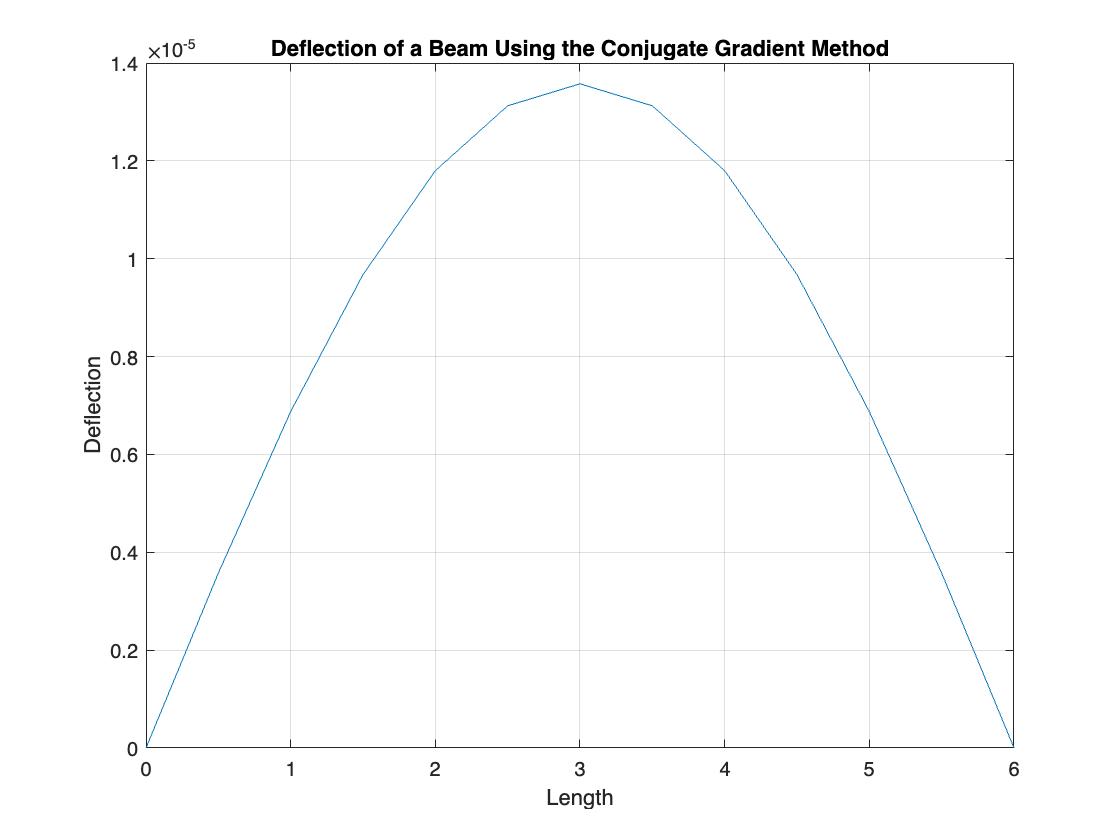

% Plotting the approximate solution curve u(x) for 0<=x<=L. 
% Be sure to label the axes and provide the title of your graph. 
u_plot2 = zeros(13,1);
u_plot2(2:end-1) = u_approx2;
plot(x, u_plot2)
title('Deflection of a Beam Using the Conjugate Gradient Method')
xlabel('Length')
ylabel('Deflection')
grid on

function [u_approx2, NumIter]=ConjugateGradient(A,b,u0,TOL,MaxIter)
% This function solves the system of linear equations Au=b for u. A must be
% symmetric. b must be a column vector with as many rows as A.

    u_approx2 = u0; % Initial approximation
    r = b - A * u_approx2; % Residual
    error = norm(r, inf); % Error
    NumIter = 1; % Iteration count
    p = -r; % First direction

    while error > TOL && NumIter < MaxIter
    
    % Calculate how far to travel to next approx (alpha)
    z = A*p; 
    s = p'*z;
    t = (r'*p)/s;

    % Update next approx
    u_new = u_approx2 + t*p;
    
    % Update residual
    r = r - t*z;
    
    % Update search direction
    B = (r'*z)/s;
    
    % Update conjugte vector using projection of previous vector
    p = -r + B*p;

    % Recalculate error
    error = norm(r, inf);

    % Overwrite x_approx
    u_approx2 = u_new;

    % Update iteration
    NumIter = NumIter + 1;
        
    end
    
end